# Hurricane Harvey Analysis 

## Background and Scope

This report provides an overview of the data import and preprocessing steps performed for the "StormEvents_2017_finalProject.csv" dataset. 

### Import the Data

The data was imported into MATLAB using the "importdata2017" function. This function is custom-made for loading the specific dataset. 

clear;
close;
clc;

format longG;

data = importdata2017("StormEvents_2017_finalProject.csv");

A few sample rows of the "data" table are shown below:

head(data,5);

      State       Month       Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon 
    __________    _____    _________________    __________    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________    _

### Two States Most Impacted by Harvey

The focus of this section is to identify and analyze storm events related to Hurricane Harvey in specific states. The states impacted by Harvey include:

- Arkansas

- Kentucky

- Louisiana

- Mississippi

- North Carolina

- Tennessee

- Texas

For our analysis, we assume that the Harvey related events occurred between the 17th of August and the 3rd of September in the year 2017. 

The resulting "data_Harvey" table contains the storm events related to Hurricane Harvey in the specified states during the defined period. This filtered dataset can now be used for further analysis and visualization specific to the impact of Hurricane Harvey on the mentioned states.

Harvey_States = upper({'Arkansas', 'Kentucky', 'Louisiana', 'Mississippi', ...
    'North Carolina', 'Tennessee', 'Texas'});

data_Harvey = data(data.Begin_Date_Time>=datetime(2017,8,17)...
    & data.Begin_Date_Time<=datetime(2017,9,3)...
    & data.End_Date_Time<=datetime(2017,9,3)...
    & ismember(data.State, Harvey_States)...
    & data.Event_Type ~= 'Heat',:);

data_Harvey.State = removecats(data_Harvey.State);
data_Harvey.Event_Type = removecats(data_Harvey.Event_Type);

A few sample rows of the "data_Harvey" table are shown below:

head(data_Harvey,5);

        State           Month        Event_Type       CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon 
    ______________    _________    ______________    __________    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________   

Group the filtered "data_Harvey" table based on the "State" column. The resulting "summary_table_Harvey_States" presents a summary of each state's impact. 

The "summary_table_Harvey_States" table provides a concise overview of the states impacted by Hurricane Harvey and the corresponding counts of Harvey-related events in each state.

To identify the two states most impacted by Hurricane Harvey, sort the "summary_table_Harvey_States" in descending order based on the "GroupCount" column. 

The two states with the highest count of Harvey-related events are obtained from the sorted summary table. Extract the names of the two most impacted states and store them in the variable "TwoMostImpactedStates". Thus, the most affected states are Texas and Louisiana.

summary_table_Harvey_States = groupsummary(data_Harvey,"State");

summary_table_Harvey_States = sortrows(summary_table_Harvey_States, "GroupCount", "descend")

summary_table_Harvey_States = 7×2 table
        State         GroupCount
    ______________    __________

    TEXAS                258    
    LOUISIANA             68    
    NORTH CAROLINA        59    
    TENNESSEE             45    
    ARKANSAS              36    
    MISSISSIPPI           31    
    KENTUCKY              20    


TwoMostImpactedStates = summary_table_Harvey_States.State(1:2)

TwoMostImpactedStates = 2×1 categorical array
     TEXAS 
     LOUISIANA 


### Table of Events for Texas and Louisiana

To focus on the events that occurred in the two most impacted states, the "events_TMIS" table is created from the filtered "data_Harvey" table. This new table contains only the events that belong to Texas and Louisiana.

events_TMIS = data_Harvey(...
    ismember(data_Harvey.State,TwoMostImpactedStates),:);

events_TMIS.State = removecats(events_TMIS.State);
events_TMIS.Event_Type = removecats(events_TMIS.Event_Type);

A few sample rows of the "events_TMIS" table are shown below:

head(events_TMIS,5);

    State    Month       Event_Type        CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _____    ______    ______________    ___________    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________    _____________<

## Visualizations

The main purpose of this visualization is to provide a spatial representation of the distribution of events in the affected regions.

### Figure of Event Types

To visualize the distribution of events related to Hurricane Harvey in the two most impacted states, Texas and Louisiana, a heatmap was generated using the "events_TMIS" table.

The heatmap displays the number of occurrences for each event type in Texas and Louisiana. Each cell in the heatmap represents the count of events of a particular type in a specific state.

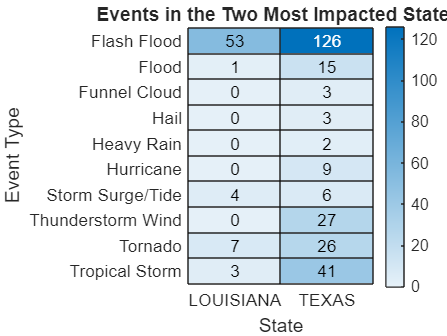

figure();
heatmap(events_TMIS,"State","Event_Type");
xlabel("State");
ylabel("Event Type");
title("Events in the Two Most Impacted States ");

### Figure of Event Locations

In the "Event Locations" plot, the geographic locations of weather events related to Hurricane Harvey in Texas and Louisiana are displayed. Before plotting the data, all missing values were removed from the dataset to ensure accurate visualization. The variable "State1Plot" ans "State2Plot" contains the filtered data for Texas and Louisiana respective. These datasets represent only valid events with available latitude and longitude information.

State1Plot = events_TMIS(~isnan(events_TMIS.Begin_Lat)...
       & events_TMIS.State==TwoMostImpactedStates(1),:);

A few sample rows of the "State1Plot" table are shown below:

head(State1Plot,5)

    State    Month        Event_Type        CZ_Name      Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat     End_Lon 
    _____    ______    _________________    _______    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________    _____________<

State2Plot = events_TMIS(~isnan(events_TMIS.Begin_Lat)...
       & events_TMIS.State==TwoMostImpactedStates(2),:);

A few sample rows of the "State2Plot" table are shown below:

head(State2Plot,5)

      State      Month     Event_Type      CZ_Name       Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon 
    _________    ______    ___________    _________    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________    _____________</

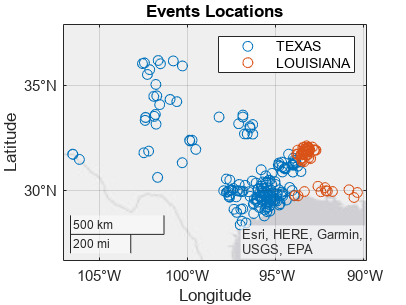

figure();
geoscatter(State1Plot.Begin_Lat,State1Plot.Begin_Lon)
hold on;
geoscatter(State2Plot.Begin_Lat,State2Plot.Begin_Lon)
hold off;

legend(string(TwoMostImpactedStates(1)),string(TwoMostImpactedStates(2)));
title("Events Locations");

The "Event Locations" plot provides valuable insights into the spatial distribution of weather events, offering a visual representation of the impact of Hurricane Harvey on both states. It helps researchers and analysts identify clusters and patterns of events in each region, aiding in the assessment of the hurricane's geographical reach and severity.

## Analysis

In this section, the data has been prepared for further analysis by isolating events in the two most impacted states. Subsets of the dataset were created, namely "State1" containing events in Texas and "State2" containing events in Louisiana. These subsets will serve as the basis for deeper exploration and examination of the weather events that occurred in each county of the states.

State1 = events_TMIS(events_TMIS.State==TwoMostImpactedStates(1),:);

A few sample rows of the "State1" table are shown below:

head(State1,5);

    State    Month       Event_Type        CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _____    ______    ______________    ___________    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________    _____________<

State2 = events_TMIS(events_TMIS.State==TwoMostImpactedStates(2),:);

A few sample rows of the "State2" table are shown below:

head(State2,5);

      State      Month       Event_Type        CZ_Name         Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon 
    _________    ______    ______________    ____________    ___________________    ___________________    _______________    _________________    _____________    _______________    _______________    ___

### Three Counties with Most Events in Texas

The objective is to gain insights into the regions that were most severely affected by Hurricane Harvey and understand the areas that require special attention and resources in terms of disaster response and recovery efforts.

To achieve this analysis, a dataset named "State1" was prepared by filtering all the events that occurred in Texas during the specified time frame related to Hurricane Harvey. The "State1" dataset was further used to perform a group summary based on county names ("CZ_Name") to count the occurrences of events in each county within Texas.

ThreeCountiesS1 = groupcounts(State1,"CZ_Name");
ThreeCountiesS1 = sortrows(ThreeCountiesS1, "GroupCount", "descend");

A few sample rows of the "ThreeCountiesS1" table are shown below:

head(ThreeCountiesS1,5);

     CZ_Name     GroupCount        Percent     
    _________    __________    ________________

    HARRIS           20        7.75193798449612
    GALVESTON        17        6.58914728682171
    FORT BEND        13        5.03875968992248
    BRAZORIA         12        4.65116279069767
    ANGELINA         11        4.26356589147287



Top3S1ME = ThreeCountiesS1.CZ_Name(1:3)

Top3S1ME = 3×1 categorical array
     HARRIS 
     GALVESTON 
     FORT BEND 


From the analysis, the three counties with the highest number of events in Texas during Hurricane Harvey were identified as follows:

- Harris

- Galveston

- Fort Bend

### Three Counties with Most Events in Louisiana

ThreeCountiesS2 = groupcounts(State2,"CZ_Name");
ThreeCountiesS2 = sortrows(ThreeCountiesS2, "GroupCount", "descend");

A few sample rows of the "ThreeCountiesS2" table are shown below:

head(ThreeCountiesS2,5);

      CZ_Name       GroupCount        Percent     
    ____________    __________    ________________

    NATCHITOCHES        20        29.4117647058824
    SABINE              14        20.5882352941176
    RED RIVER            8        11.7647058823529
    WINN                 5        7.35294117647059
    VERMILION            4        5.88235294117647



Top3S2ME = ThreeCountiesS2.CZ_Name(1:3)

Top3S2ME = 3×1 categorical array
     NATCHITOCHES 
     SABINE 
     RED RIVER 


A similar analysis for Louisiana yielded the following counties:

- Natchitoches

- Sabine

- Red River

These counties had the highest number of weather-related events during Hurricane Harvey in Louisiana.

### Three Counties with Highest Property Cost in Texas

For the analysis of property costs in Texas the relevant columns, were extracted for further analysis.

Next, a summary of property costs for each county was computed using the groupsummary function, grouping the data by "CZ_Name" and summing the "Property_Cost" values for each county. The results were sorted in descending order based on the total property cost.

State1PC = State1(~isnan(State1.Property_Cost),["State" "CZ_Name" "Event_Type" "Property_Cost"]);

A few sample rows of the "State1PC" table are shown below:

head(State1PC,5);

    State      CZ_Name        Event_Type      Property_Cost
    _____    ___________    ______________    _____________

    TEXAS    MONTGOMERY     Tropical Storm      7000000000 
    TEXAS    FORT BEND      Tropical Storm      8000000000 
    TEXAS    GALVESTON      Tropical Storm     10000000000 
    TEXAS    SAN JACINTO    Tropical Storm       350000000 
    TEXAS    WALKER         Tropical Storm       600000000 



ThreeCountiesS1PC = groupsummary(State1PC,"CZ_Name","sum","Property_Cost");

ThreeCountiesS1PC = sortrows(ThreeCountiesS1PC, "sum_Property_Cost", "descend");

A few sample rows of the "ThreeCountiesS1PC" table are shown below:

head(ThreeCountiesS1PC,5);

     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17           20000201500   
    FORT BEND         13           16004330000   
    MONTGOMERY         6           14000000000   
    HARRIS            20           10000730000   
    JEFFERSON          4            3000000000   



Top3S1PC = ThreeCountiesS1PC.CZ_Name(1:3)

Top3S1PC = 3×1 categorical array
     GALVESTON 
     FORT BEND 
     MONTGOMERY 


The top three counties with the highest reported property costs in Texas were identified as follows:

- Galveston: With a reported property cost of $20,000,201,500

- Fort Bend: With a reported property cost of $16,004,330,000

- Montgomery: With a reported property cost of $14,000,000,000

### Three Counties with Highest Property Cost in Louisiana

State2PC = State2(~isnan(State2.Property_Cost),["State" "CZ_Name" "Event_Type" "Property_Cost"]);

A few sample rows of the "State2PC" table are shown below:

head(State2PC,5);

      State        CZ_Name         Event_Type      Property_Cost
    _________    ____________    ______________    _____________

    LOUISIANA    SABINE          Tropical Storm          0      
    LOUISIANA    NATCHITOCHES    Tropical Storm          0      
    LOUISIANA    UNION           Tropical Storm          0      
    LOUISIANA    SABINE          Flash Flood             0      
    LOUISIANA    SABINE          Flash Flood             0      



ThreeCountiesS2PC = groupsummary(State2PC,"CZ_Name","sum","Property_Cost");

ThreeCountiesS2PC = sortrows(ThreeCountiesS2PC, "sum_Property_Cost", "descend");

A few sample rows of the "ThreeCountiesS2PC" table are shown below:

head(ThreeCountiesS2PC,5);

     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1             60000000     
    BEAUREGARD        1             15000000     
    ACADIA            1               200000     
    CAMERON           3                72000     
    VERMILION         4                 5000     



Top3S2PC = ThreeCountiesS2PC.CZ_Name(1:3)

Top3S2PC = 3×1 categorical array
     CALCASIEU 
     BEAUREGARD 
     ACADIA 


A similar analysis for Louisiana yielded the following counties in Louisiana with the highest reported property costs related to Hurricane Harvey are as follows:

- Calcasieu: With a reported property cost of $60,000,000

- Beauregard: With a reported property cost of $15,000,000

- Acadia: With a reported property cost of $200,000

## Conclusions and Recommendations

Based on the data analysis conducted for the events related to Hurricane Harvey in Texas and Louisiana, the following recommendation is proposed:

Recommendation: Send outside contractors to assist with claims filing in the following counties.

For Texas:

- Harris

- Galveston

- Fort Bend

For Louisiana:

- Natchitoches

- Sabine

- Red River

These counties were identified as the most impacted regions in their respective states based on the number of events and reported property costs.